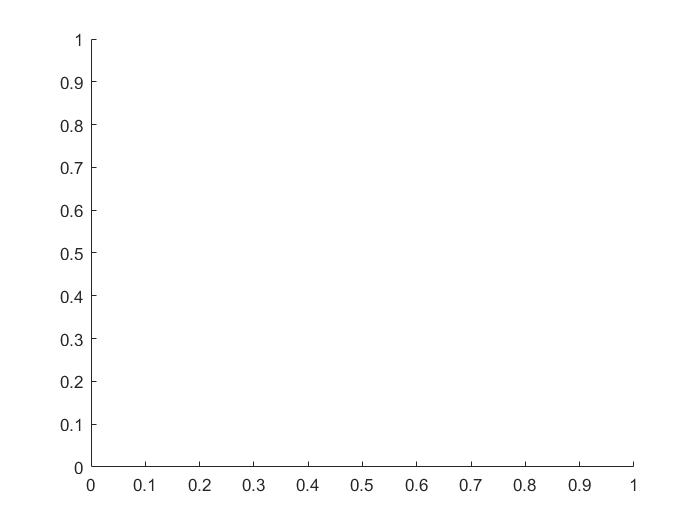

itterations=10000;
difference=[asin(sin(f(1)))];
outputs=[asin(sin(f(1)))];
for i=2:itterations
    outputs(i)=asin(sin(f(i)));
    difference(i)=difference(i-1)+outputs(i);
end
hold on

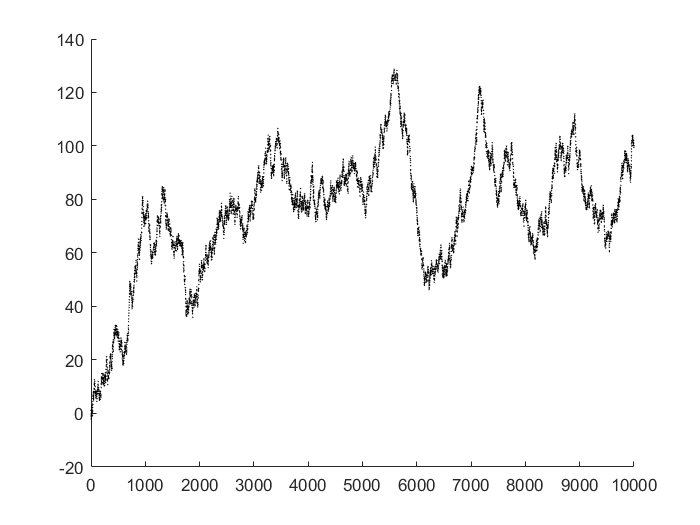

figure;
scatter(1:itterations,difference,1,'black','filled');
xlim([0 itterations]);
hold off
hold on

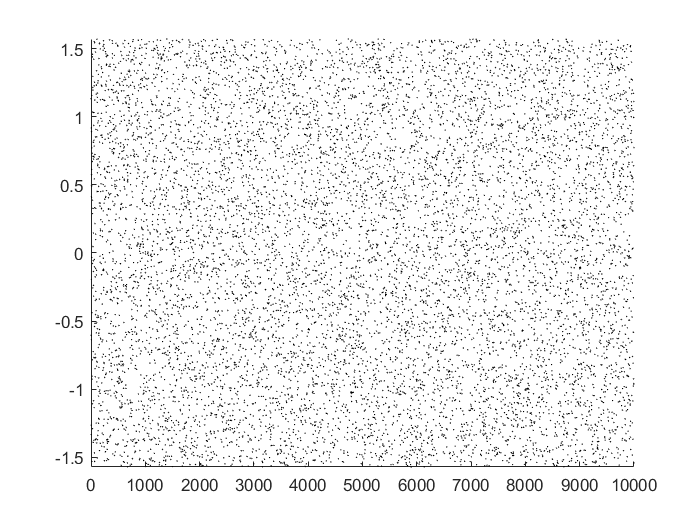

figure;
scatter(1:itterations,outputs,1,'black','filled');
xlim([0 itterations]);
ylim([-pi/2 pi/2]);
hold off

function y = f(x)
    y=1.01^x+x^2;
end